
%% Define the plant transfer function and convert to SS
num = 500;                     % numerator coefficients
den = [1 10 21 0];             % denominator coefficients
Gp  = tf(num,den);

sys = ss(Gp,'min');            % minimal-realisation (already CCF for SISO)

fprintf('---Controllable canonical form---\n');

---Controllable canonical form---


A = sys.A,  B = sys.B,  C = sys.C,  D = sys.D

A =   -10.0000   -5.2500         0
    4.0000         0         0
         0    0.2500         0


B =     16
     0
     0


C =          0         0   31.2500


D = 0


%% 1.  Check controllability & observability
Co = ctrb(A,B);    Ob = obsv(A,C);

if rank(Co)==size(A,1)
    disp('System is completely controllable.');
else
    error('System NOT controllable'); 
end

System is completely controllable.


if rank(Ob)==size(A,1)
    disp('System is completely observable.');
else
    error('System NOT observable');
end

System is completely observable.



%% 2.  Desired dominant poles from spec (15 % OS, 1 s Ts @ 2 %)
PO  = 0.15;               % Percent overshoot
Ts  = 1;                  % 2 % settling time

zeta   = -log(PO)/sqrt(pi^2+log(PO)^2);              % damping ratio
wn     = 4/(zeta*Ts);                                % natural frequency
sigma  = zeta*wn;                                    % real part
wd     = wn*sqrt(1-zeta^2);                          % imag. part

p1 = -sigma + 1j*wd;                                 % dominant pair
p2 = -sigma - 1j*wd;
p3 = 10*real(p1);                                    % third pole 10× faster

desired_poles = [p3, p1, p2];
fprintf('\n---Chosen closed-loop poles---\n');


---Chosen closed-loop poles---


disp(desired_poles.');

 -40.0000 + 0.0000i
  -4.0000 + 6.6239i
  -4.0000 - 6.6239i




%% 3.  State-feedback gain K  (place / acker give same result for SISO)
K  = place(A,B,desired_poles);       % 1×3 row vector
disp('State-feedback K ='), disp(K);

State-feedback K =
    2.3750    5.6074  149.6908




Acl = A - B*K;                       % closed-loop matrix
sys_cl = ss(Acl,B,C,D);


%% 4.  Observer design  (poles 5× faster than controller real part)
obs_factor = 5;
p_obs = obs_factor*real(desired_poles) ...
        + 1j*imag(desired_poles)*obs_factor;  % same shape, farther left
L   = place(A',C',p_obs)';          % observer gain (note transpose trick)
disp('Observer gain L ='), disp(L);

Observer gain L =
   1.0e+03 *

    7.1294
    0.9185
    0.0074




%% 5.  Build estimator-in-forward-loop architecture
% Augmented system  [x_dot ; e_dot] where e = x̂ - x
Aobs = [ A-B*K , B*K ;
         zeros(size(A)) , A-L*C ];
Bobs = [ B ; zeros(size(B)) ];
Cobs = [ C , zeros(size(C)) ];
Dobs = D;

sys_aug = ss(Aobs,Bobs,Cobs,Dobs);


%% 6.  Time-domain verification
t = 0:0.001:3;                 % fine grid for 3 s horizon
[y,~,x] = step(sys_aug,t);

% Key performance metrics
info = stepinfo(y,t);
fprintf('\n---Step-response metrics (with estimator in loop)---\n');


---Step-response metrics (with estimator in loop)---


disp(info);

         RiseTime: 0.2216
    TransientTime: 1.0364
     SettlingTime: 1.0364
      SettlingMin: 0.1879
      SettlingMax: 0.2394
        Overshoot: 14.6866
       Undershoot: 0
             Peak: 0.2394
         PeakTime: 0.5020



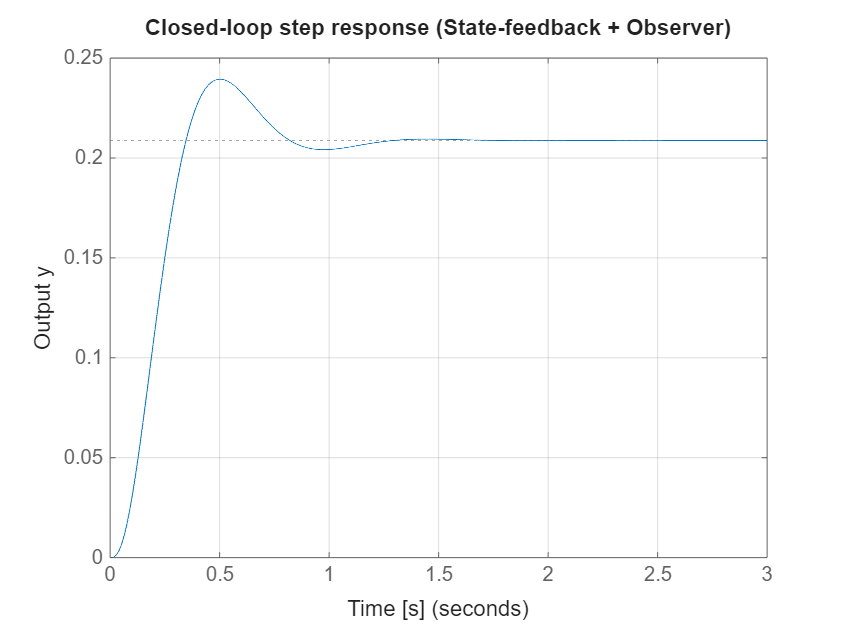


%% 7.  Plots
figure;
step(sys_aug,t), grid on;
title('Closed-loop step response (State-feedback + Observer)');
xlabel('Time [s]'); ylabel('Output y');


%% 8.  Numeric display (optional)
fprintf('\nEigenvalues of A-BK (controller):\n'); disp(eig(Acl).');


Eigenvalues of A-BK (controller):
 -40.0000 + 0.0000i  -4.0000 + 6.6239i  -4.0000 - 6.6239i



fprintf('Eigenvalues of A-LC (observer):\n');  disp(eig(A-L*C).');

Eigenvalues of A-LC (observer):
   1.0e+02 *

  -0.2000 + 0.3312i  -0.2000 - 0.3312i  -2.0000 + 0.0000i

